# Neurodata Without Borders Extracellular Electrophysiology Tutorial

## About This Tutorial

This tutorial describes storage of hypothetical data from extracellular electrophysiology experiments in NWB for the following data categories:

- Raw voltage recording

- Local field potential (LFP) and filtered electrical signals

- Spike times

## Before You Begin

It is recommended to first work through the [Introduction to MatNWB tutorial](matlab:open('./intro.mlx')), which demonstrates installing MatNWB and creating an NWB file with subject information, animal position, and trials, as well as writing and reading NWB files in MATLAB.

**Important**: The dimensions of timeseries data in MatNWB should be defined in the opposite order of how it is defined in the nwb-schemas. In NWB, time is always stored in the first dimension of the data, whereas in MatNWB time should be stored in the last dimension of the data. This is explained in more detail here: [MatNWB <-> HDF5 Dimension Mapping](matlab:open('./dimensionMapNoDataPipes.mlx')).

## Setting up the NWB File

An NWB file represents a single session of an experiment. Each file must have a `session_description`, `identifier`, and `session_start_time`. Create a new [`NWBFile`](https://matnwb.readthedocs.io/en/latest/pages/functions/NwbFile.html) object these required fields along with any additional metadata. In MatNWB, arguments are specified using MATLAB's keyword argument pair convention, where each argument name is followed by its value.

nwb = NwbFile( ...
    'session_description', 'mouse in open exploration',...
    'identifier', 'Mouse5_Day3', ...
    'session_start_time', datetime(2018, 4, 25, 2, 30, 3, 'TimeZone', 'local'), ...
    'timestamps_reference_time', datetime(2018, 4, 25, 3, 0, 45, 'TimeZone', 'local'), ...
    'general_experimenter', 'Last Name, First Name', ... % optional
    'general_session_id', 'session_1234', ... % optional
    'general_institution', 'University of My Institution', ... % optional
    'general_related_publications', {'DOI:10.1016/j.neuron.2016.12.011'}); % optional
nwb

nwb =   NwbFile with properties:

                                             nwb_version: '2.9.0'
                                        file_create_date: []
                                              identifier: 'Mouse5_Day3'
                                     session_description: 'mouse in open exploration'
                                      session_start_time: {[2018-04-25T02:30:03.000000+02:00]}
                               timestamps_reference_time: {[2018-04-25T03:00:45.000000+02:00]}
                                             acquisition: [0×1 types.untyped.Set]
                                                analysis: [0×1 types.untyped.Set]
                                                 general: [0×1 types.untyped.Set]
                                 general_data_collection: ''
                                         general_devices: [0×1 types.untyped.Set]
                                  g

## Electrode Information

In order to store extracellular electrophysiology data, you first must create an electrodes table describing the electrodes that generated this data. Extracellular electrodes are stored in an `electrodes` table, which is also a [`DynamicTable`](https://matnwb.readthedocs.io/en/latest/pages/neurodata_types/hdmf_common/DynamicTable.html). `electrodes` has several required fields: `x`, `y`, `z`, `impedance`, `location`, `filtering`, and `electrode_group`.

The electrodes table references a required [`ElectrodeGroup`](https://matnwb.readthedocs.io/en/latest/pages/neurodata_types/core/ElectrodeGroup.html), which is used to represent a group of electrodes. Before creating an [`ElectrodeGroup`](https://matnwb.readthedocs.io/en/latest/pages/neurodata_types/core/ElectrodeGroup.html), you must define a [`Device`](https://matnwb.readthedocs.io/en/latest/pages/neurodata_types/core/Device.html) object. The fields `description`, `serial_number` and `model` are optional, but recommended. The `model` property can contain a [`DeviceModel`](https://matnwb.readthedocs.io/en/latest/pages/neurodata_types/core/DeviceModel.html) object which stores information about the device model. This property can be useful when searching a set of NWB files or a data archive for all files that use a specific device model (e.g., Neuropixels probe).

device_model = types.core.DeviceModel( ...
     'manufacturer', 'Array Technologies', ...
     'model_number', 'PRB_1_4_0480_123', ...
     'description', 'Neurovoxels 0.99 - A 12-channel array with 4 shanks and 3 channels per shank' ...
);
% Add device model to nwb object
nwb.general_devices_models.set('Neurovoxels 0.99', device_model);


device = types.core.Device(...
    'description', 'A 12-channel array with 4 shanks and 3 channels per shank', ...
    'serial_number', '1234567890', ...
    'model', device_model ...
);

% Add device to nwb object
nwb.general_devices.set('array', device);

### Electrodes Table

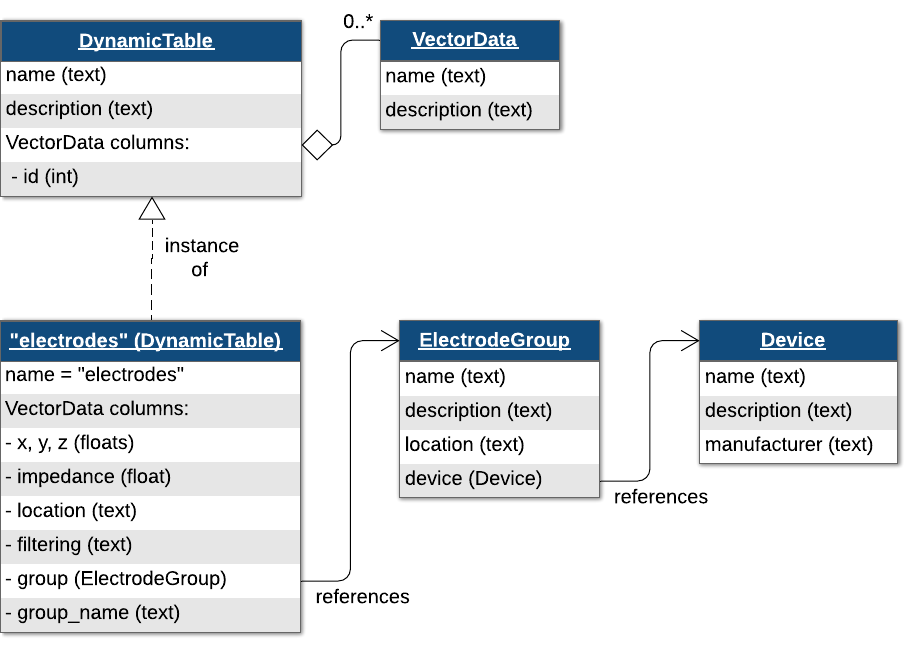

Since this is a [`DynamicTable`](https://matnwb.readthedocs.io/en/latest/pages/neurodata_types/hdmf_common/DynamicTable.html), we can add additional metadata fields. We will be adding a "label" column to the table.

numShanks = 4;
numChannelsPerShank = 3;
numChannels = numShanks * numChannelsPerShank;

electrodesDynamicTable = types.core.ElectrodesTable(...
    'colnames', {'location', 'group', 'group_name', 'label'}, ...
    'description', 'all electrodes');

for iShank = 1:numShanks
    shankGroupName = sprintf('shank%d', iShank);
    electrodeGroup = types.core.ElectrodeGroup( ...
        'description', sprintf('electrode group for %s', shankGroupName), ...
        'location', 'brain area', ...
        'device', types.untyped.SoftLink(device) ...
    );
    
    nwb.general_extracellular_ephys.set(shankGroupName, electrodeGroup);
    for iElectrode = 1:numChannelsPerShank
        electrodesDynamicTable.addRow( ...
            'location', 'unknown', ...
            'group', types.untyped.ObjectView(electrodeGroup), ...
            'group_name', shankGroupName, ...
            'label', sprintf('%s-electrode%d', shankGroupName, iElectrode));
    end
end
electrodesDynamicTable.toTable() % Display the table

ans = 12×5 table
    id     location                 group                group_name            label        
    __    ___________    ____________________________    __________    _____________________

     0    {'unknown'}    1×1 types.untyped.ObjectView    {'shank1'}    {'shank1-electrode1'}
     1    {'unknown'}    1×1 types.untyped.ObjectView    {'shank1'}    {'shank1-electrode2'}
     2    {'unknown'}    1×1 types.untyped.ObjectView    {'shank1'}    {'shank1-electrode3'}
     3    {'unknown'}    1×1 types.untyped.ObjectView    {'shank2'}    {'shank2-electrode1'}
     4    {'unknown'}    1×1 types.untyped.ObjectView    {'shank2'}    {'shank2-electrode2'}
     5    {'unknown'}    1×1 types.untyped.ObjectView    {'shank2'}    {'shank2-electrode3'}
     6    {'unknown'}    1×1 types.untyped.ObjectView    {'shank3'} 

nwb.general_extracellular_ephys_electrodes = electrodesDynamicTable;

### Links

In the above loop, we create [`ElectrodeGroup`](https://matnwb.readthedocs.io/en/latest/pages/neurodata_types/core/ElectrodeGroup.html) objects. The `electrodes` table then uses an `ObjectView` in each row to link to the corresponding [`ElectrodeGroup`](https://matnwb.readthedocs.io/en/latest/pages/neurodata_types/core/ElectrodeGroup.html) object. An `ObjectView` is a construct that enables linking one neurodata type to another, allowing a neurodata type to reference another within the NWB file.

## Recorded Extracellular Signals

Voltage data are stored using the [`ElectricalSeries`](https://matnwb.readthedocs.io/en/latest/pages/neurodata_types/core/ElectricalSeries.html) class, a subclass of the [`TimeSeries`](https://matnwb.readthedocs.io/en/latest/pages/neurodata_types/core/TimeSeries.html) class specialized for voltage data. 

### Referencing Electrodes

In order to create our [`ElectricalSeries`](https://matnwb.readthedocs.io/en/latest/pages/neurodata_types/core/ElectricalSeries.html) object, we first need to reference a set of rows in the `electrodes` table to indicate which electrode (channel) each entry in the electrical series were recorded from. We will do this by creating a [`DynamicTableRegion`](https://matnwb.readthedocs.io/en/latest/pages/neurodata_types/hdmf_common/DynamicTableRegion.html), which is a type of link that allows you to reference specific rows of a [`DynamicTable`](https://matnwb.readthedocs.io/en/latest/pages/neurodata_types/hdmf_common/DynamicTable.html), such as the `electrodes` table, using row indices.

Create a [`DynamicTableRegion`](https://matnwb.readthedocs.io/en/latest/pages/neurodata_types/hdmf_common/DynamicTableRegion.html) that references all rows of the `electrodes` table.

electrode_table_region = types.hdmf_common.DynamicTableRegion( ...
    'table', types.untyped.ObjectView(electrodesDynamicTable), ...
    'description', 'all electrodes', ...
    'data', (0:length(electrodesDynamicTable.id.data)-1)');

### Raw Voltage Data

Now create an [`ElectricalSeries`](https://matnwb.readthedocs.io/en/latest/pages/neurodata_types/core/ElectricalSeries.html) object to hold acquisition data collected during the experiment.

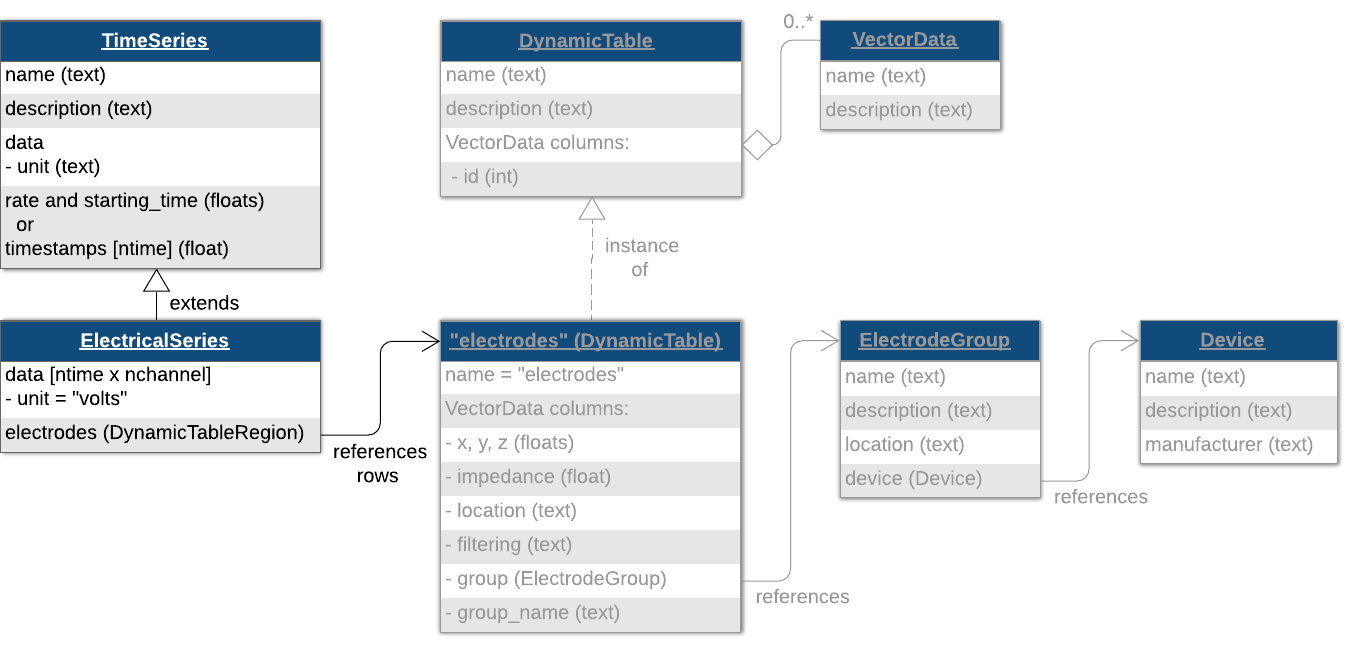

raw_electrical_series = types.core.ElectricalSeries( ...
    'starting_time', 0.0, ... % seconds
    'starting_time_rate', 30000., ... % Hz
    'data', randn(numChannels, 3000), ... % nChannels x nTime
    'electrodes', electrode_table_region, ...
    'data_unit', 'volts');

This is the voltage data recorded directly from our electrodes, so it goes in the acquisition group.

nwb.acquisition.set('ElectricalSeries', raw_electrical_series);

## Processed Extracellular Electrical Signals

### LFP

LFP refers to data that has been low-pass filtered, typically below 300 Hz. This data may also be downsampled. Because it is filtered and potentially resampled, it is categorized as processed data. LFP data would also be stored in an [`ElectricalSeries`](https://matnwb.readthedocs.io/en/latest/pages/neurodata_types/core/ElectricalSeries.html). To help data analysis and visualization tools know that this [`ElectricalSeries`](https://matnwb.readthedocs.io/en/latest/pages/neurodata_types/core/ElectricalSeries.html) object represents LFP data, we store it inside an [`LFP`](https://matnwb.readthedocs.io/en/latest/pages/neurodata_types/core/LFP.html) object and then place the [`LFP`](https://matnwb.readthedocs.io/en/latest/pages/neurodata_types/core/LFP.html) object in a [`ProcessingModule`](https://matnwb.readthedocs.io/en/latest/pages/neurodata_types/core/ProcessingModule.html) named `'ecephys'`. This is analogous to how we stored the [`SpatialSeries`](https://matnwb.readthedocs.io/en/latest/pages/neurodata_types/core/SpatialSeries.html) object inside of a [`Position`](https://matnwb.readthedocs.io/en/latest/pages/neurodata_types/core/Position.html) object and stored the [`Position`](https://matnwb.readthedocs.io/en/latest/pages/neurodata_types/core/Position.html) object in a [`ProcessingModule`](https://matnwb.readthedocs.io/en/latest/pages/neurodata_types/core/ProcessingModule.html) named `'behavior'` in the [behavior](matlab:open('./behavior.mlx')) tutorial

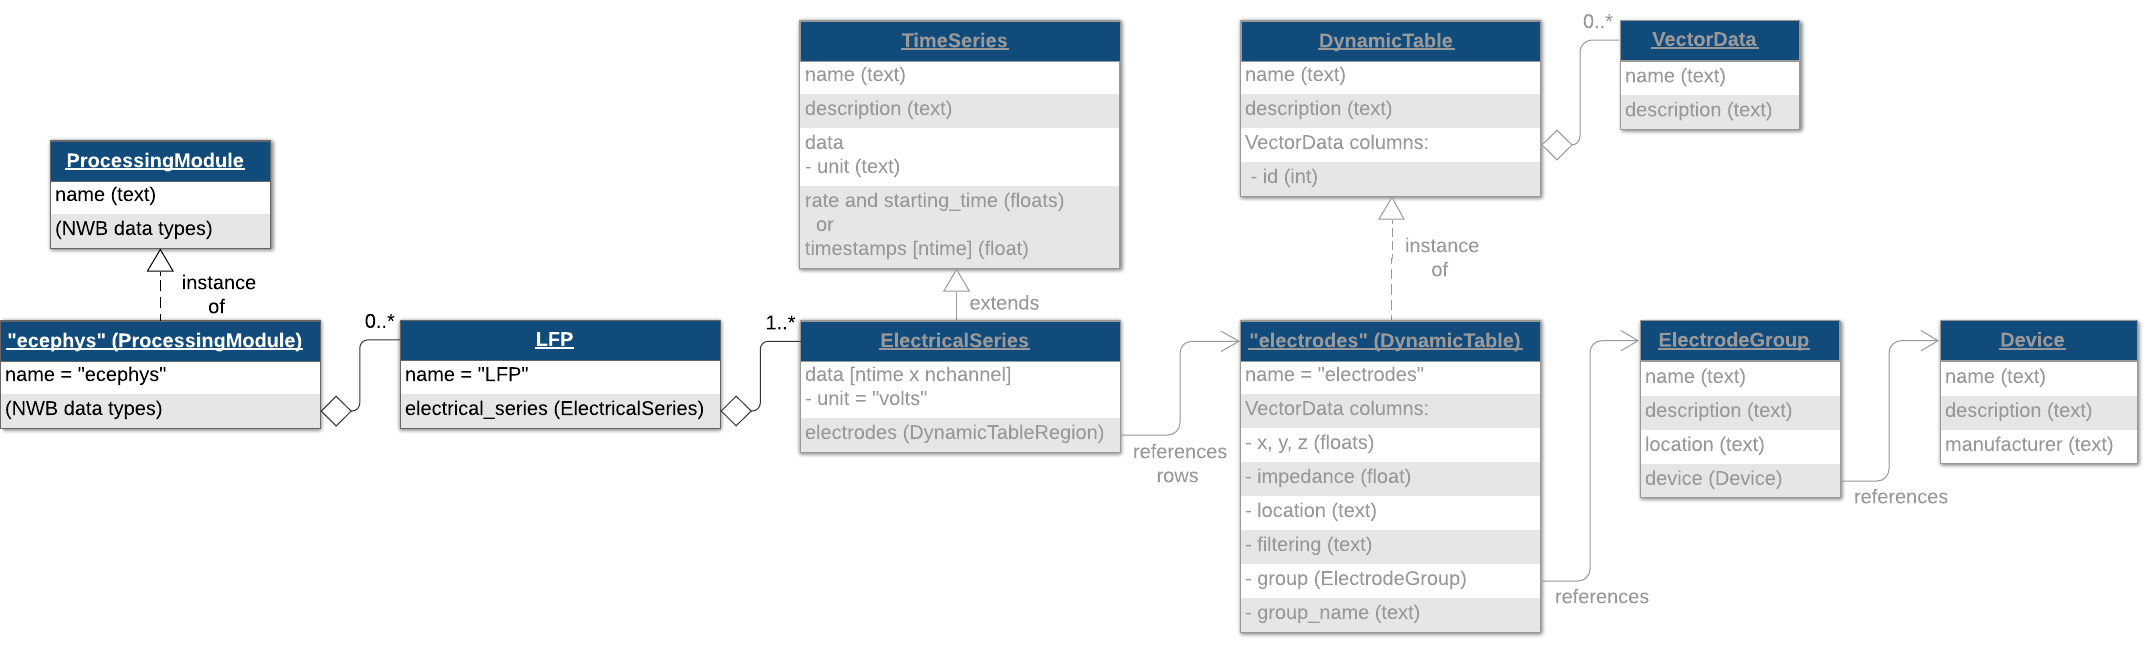

lfp_electrical_series = types.core.ElectricalSeries( ...
    'starting_time', 0.0, ... % seconds
    'starting_time_rate', 1000., ... % Hz
    'data', randn(numChannels, 100), ... nChannels x nTime
    'filtering', 'Low-pass filter at 300 Hz', ...
    'electrodes', electrode_table_region, ...
    'data_unit', 'volts');

lfp = types.core.LFP('ElectricalSeries', lfp_electrical_series);

ecephys_module = types.core.ProcessingModule(...
    'description', 'extracellular electrophysiology');

ecephys_module.nwbdatainterface.set('LFP', lfp);
nwb.processing.set('ecephys', ecephys_module);

### Other Types of Filtered Electrical Signals

If your acquired data is filtered for frequency ranges other than LFP—such as Gamma or Theta—you can store the result in an [`ElectricalSeries`](https://matnwb.readthedocs.io/en/latest/pages/neurodata_types/core/ElectricalSeries.html) and encapsulate it within a [`FilteredEphys`](https://matnwb.readthedocs.io/en/latest/pages/neurodata_types/core/FilteredEphys.html) object instead of the [`LFP`](https://matnwb.readthedocs.io/en/latest/pages/neurodata_types/core/LFP.html) object.

% Generate filtered data
filtered_data = randn(50, 12); % 50 time points, 12 channels
filtered_data = permute(filtered_data, [2, 1]); % permute timeseries for matnwb

% Create an ElectricalSeries object
filtered_electrical_series = types.core.ElectricalSeries( ...
    'description', 'Data filtered in the theta range', ...
    'data', filtered_data, ...
    'electrodes', electrode_table_region, ...
    'filtering', 'Band-pass filtered between 4 and 8 Hz', ...
    'starting_time', 0.0, ...
    'starting_time_rate', 200.0 ...
    );

% Create a FilteredEphys object and add the filtered electrical series
filtered_ephys = types.core.FilteredEphys();
filtered_ephys.electricalseries.set('FilteredElectricalSeries', filtered_electrical_series);

% Add the FilteredEphys object to the ecephys module
ecephys_module.nwbdatainterface.set('FilteredEphys', filtered_ephys);

### Decomposition of LFP Data into Frequency Bands

In some cases, you may want to further process the LFP data and decompose the signal into different frequency bands for additional downstream analyses. You can then store the processed data from these spectral analyses using a [`DecompositionSeries`](https://matnwb.readthedocs.io/en/latest/pages/neurodata_types/core/DecompositionSeries.html) object. This object allows you to include metadata about the frequency bands and metric used (e.g., `power`, `phase`, `amplitude`), as well as link the decomposed data to the original [`TimeSeries`](https://matnwb.readthedocs.io/en/latest/pages/neurodata_types/core/TimeSeries.html) signal the data was derived from.

In this tutorial, the examples for [`FilteredEphys`](https://matnwb.readthedocs.io/en/latest/pages/neurodata_types/core/FilteredEphys.html) and [`DecompositionSeries`](https://matnwb.readthedocs.io/en/latest/pages/neurodata_types/core/DecompositionSeries.html) may appear similar. However, the key difference is that [`DecompositionSeries`](https://matnwb.readthedocs.io/en/latest/pages/neurodata_types/core/DecompositionSeries.html) is specialized for storing the results of spectral analyses of timeseries data in general, whereas [`FilteredEphys`](https://matnwb.readthedocs.io/en/latest/pages/neurodata_types/core/FilteredEphys.html) is defined specifically as a container for filtered electrical signals.

**Note**: When adding data to a [`DecompositionSeries`](https://matnwb.readthedocs.io/en/latest/pages/neurodata_types/core/DecompositionSeries.html), the `data` argument is assumed to be 3D where the first dimension is time, the second dimension is channels, and the third dimension is bands. As mentioned in the beginning of this tutorial, in MatNWB the data needs to be permuted because the dimensions are written to file in reverse order (See the [dimensionMapNoDataPipes](matlab:open('./dimensionMapNoDataPipes.mlx')) tutorial)

% Define the frequency bands of interest (in Hz):
band_names = {'theta'; 'beta'; 'gamma'};
band_mean = [8; 21; 55];
band_stdev = [2; 4.5; 12.5];
band_limits = [band_mean - 2*band_stdev, band_mean + 2*band_stdev];

% The bands should be added to the DecompositionSeries as a dynamic table
bands = table(band_names, band_mean, band_stdev, band_limits, ...
    'VariableNames', {'band_name', 'band_mean', 'band_stdev', 'band_limits'})

bands = 3×4 table
    band_name    band_mean    band_stdev    band_limits
    _________    _________    __________    ___________

    {'theta'}        8              2         4    12  
    {'beta' }       21            4.5        12    30  
    {'gamma'}       55           12.5        30    80  


bands = util.table2nwb( bands, 'Frequency bands for lfp', 'types.core.FrequencyBandsTable');

% Generate random phase data for the demonstration.
phase_data = randn(50, 12, numel(band_names)); % 50 samples, 12 channels, 3 frequency bands
phase_data = permute(phase_data, [3,2,1]); % See dimensionMapNoDataPipes tutorial

decomp_series = types.core.DecompositionSeries(...
    'data', phase_data, ...
    'bands', bands, ...
    'metric', 'phase', ...
    'starting_time', 0.0, ... % seconds
    'starting_time_rate', 1000.0, ... % Hz
    'source_channels', electrode_table_region, ...
    'source_timeseries', lfp_electrical_series);

% Add decomposition series to ecephys module
ecephys_module.nwbdatainterface.set('theta', decomp_series);

## Spike Times and Extracellular Events

### Sorted Spike Times

Spike times are stored in a [`Units`](https://matnwb.readthedocs.io/en/latest/pages/neurodata_types/core/Units.html) table, a specialization of the [`DynamicTable`](https://matnwb.readthedocs.io/en/latest/pages/neurodata_types/hdmf_common/DynamicTable.html) class. The default [`Units`](https://matnwb.readthedocs.io/en/latest/pages/neurodata_types/core/Units.html) table is located at `/units` in the HDF5 file. You can add columns to the [`Units`](https://matnwb.readthedocs.io/en/latest/pages/neurodata_types/core/Units.html) table just like you did for `electrodes` and `trials` (see [convertTrials](matlab:open('./convertTrials.m'))). Here, we generate some random spike time data and populate the table. Note: Spike times of a [`Units`](https://matnwb.readthedocs.io/en/latest/pages/neurodata_types/core/Units.html) table should be sorted in ascending order.

num_cells = 10;
spike_times = cell(1, num_cells);
for iShank = 1:num_cells
    spike_times{iShank} = sort( rand(1, randi([16, 28])), 'ascend');
end
spike_times

spike_times = 1×10 cell array
    {[0.0060 0.0277 0.0558 0.1369 0.2126 0.4032 0.4754 0.5799 0.5859 0.6531 0.7012 0.7272 0.7445 0.7461 0.7678 0.7858 0.8112 0.9440 0.9629 0.9675]}    {[0.0766 0.2084 0.2185 0.2285 0.2493 0.2554 0.2733 0.3336 0.3571 0.3755 0.4356 0.4472 0.5020 0.5398 0.5510 0.5927 0.5927 0.6269 0.6336 0.6396 0.6835 0.7309 0.7337 0.7849 0.8619]}    {[0.0074 0.1507 0.1701 0.1789 0.2184 0.2598 0.2889 0.3162 0.3714 0.5411 0.5755 0.5883 0.5953 0.6006 0.6921 0.7584 0.7978 0.8411 0.8881 0.9108 0.9510]}    {[0.0060 0.0092 0.0451 0.1041 0.1052 0.1175 0.2766 0.2792 0.3236 0.3489 0.3543 0.4075 0.6461 0.8302 0.8447 0.8461 0.9889]}    {[0.0643 0.1817 0.2274 0.2331 0.2334 0.2361 0.2504 0.2559 0.3564 0.3901 0.4325 0.4692 0.5340 0.5938 0.6548 0.6789 0.7262 0.7393 0.8710 0.8990 0.9198 0.9207 0.9423 0.9952]}    {[0.0471 0.1964 0.2366 0.3207 0.3795 0.4065 0.4235 0.4403 0.4996 0.5402 0.5719 0.5936 0.6623 0.6867 0.6959 0.7062 0.7388 0.7527 0.8030 0.8368 0.8788 0.9830]}    {[0.1433 0.1666 0.253

#### Ragged Arrays

Spike times are an example of a ragged array- it's like a matrix, but each row has a different number of elements. We can represent this type of data as an indexed column of the [`Units`](https://matnwb.readthedocs.io/en/latest/pages/neurodata_types/core/Units.html) table. These indexed columns have two components, the [`VectorData`](https://matnwb.readthedocs.io/en/latest/pages/neurodata_types/hdmf_common/VectorData.html) object that holds the data and the [`VectorIndex`](https://matnwb.readthedocs.io/en/latest/pages/neurodata_types/hdmf_common/VectorIndex.html) object that holds the indices in the vector that indicate the row breaks. You can use the convenience function `util.create_indexed_column` to create these objects. For more information about ragged arrays, we refer you to the **"Ragged Array Columns"** section of the [dynamic table](matlab:open('./dynamic_tables.mlx')) tutorial.

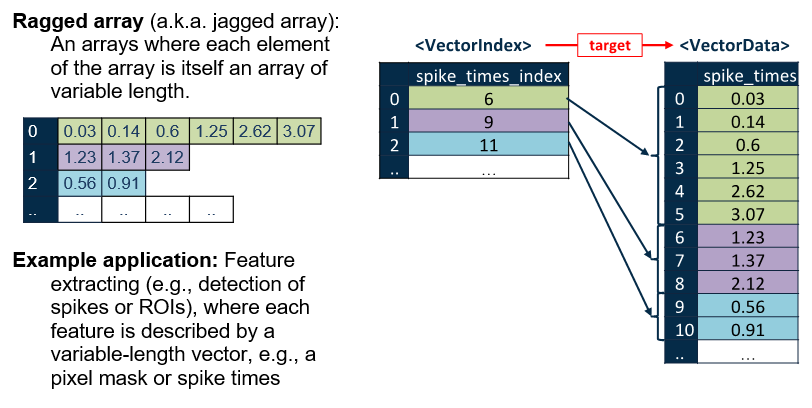

[spike_times_vector, spike_times_index] = util.create_indexed_column(spike_times);

nwb.units = types.core.Units( ...
    'colnames', {'spike_times'}, ...
    'description', 'units table', ...
    'spike_times', spike_times_vector, ...
    'spike_times_index', spike_times_index ...
);

nwb.units.toTable()

ans = 10×2 table
    id     spike_times 
    __    _____________

     1    {20×1 double}
     2    {25×1 double}
     3    {21×1 double}
     4    {17×1 double}
     5    {24×1 double}
     6    {22×1 double}
     7    {25×1 double}
     8    {19×1 double}
     9    {28×1 double}
    10    {22×1 double}


### Unsorted Spike Times

While the [`Units`](https://matnwb.readthedocs.io/en/latest/pages/neurodata_types/core/Units.html) table is used to store spike times and waveform data for spike-sorted, single-unit activity, you may also want to store spike times and waveform snippets of unsorted spiking activity. This is useful for recording multi-unit activity detected via threshold crossings during data acquisition. Such information can be stored using [`SpikeEventSeries`](https://matnwb.readthedocs.io/en/latest/pages/neurodata_types/core/SpikeEventSeries.html) objects.

% In the SpikeEventSeries the dimensions should be ordered as 
% [num_events, num_channels, num_samples].
% Define spike snippets: 20 events, 3 channels, 40 samples per event. 
spike_snippets = rand(20, 3, 40);
% Permute spike snippets (See dimensionMapNoDataPipes tutorial)
spike_snippets = permute(spike_snippets, [3,2,1]) 

spike_snippets = spike_snippets(:,:,1) =

    0.5622    0.1359    0.3372
    0.6268    0.6305    0.6465
    0.2329    0.8404    0.5672
    0.5596    0.0263    0.8194
    0.2888    0.4745    0.8291
    0.8917    0.6216    0.0113
    0.3455    0.5433    0.0280
    0.6256    0.4126    0.0097
    0.3896    0.8552    0.8985
    0.5427    0.3275    0.4961
    0.8487    0.0415    0.5741
    0.1619    0.8188    0.7822
    0.6736    0.9478    0.0947
    0.1356    0.0052    0.3502
    0.5127    0.0421    0.8319
    0.8034    0.7258    0.1899
    0.8954    0.4829    0.5376
    0.5483    0.5880    0.2025
    0.8967    0.8292    0.4187
    0.1019    0.8623    0.7015
    0.3290    0.8723    0.3701
    0.6169    0.7581    0.6597
    0.4238    0.9206    0.5109
    0.5679    0.2267    0.1113
    0.7034    0.7181    0.1357
    0.9288    0.3483    0.1355
    0.1124    0.4025    0.0897
    0.8787    0.0177    0.5189
    0.0944    0.0932    0.1001
    0.3057    0.1749    0.6634
    0.9918    0.8791    0.60


% Create electrode table region referencing electrodes 0, 1, and 2
shank0_table_region = types.hdmf_common.DynamicTableRegion( ...
    'table', types.untyped.ObjectView(electrodesDynamicTable), ...
    'description', 'shank0', ...
    'data', (0:2)');

% Define spike event series for unsorted spike times
spike_events = types.core.SpikeEventSeries( ...
    'data', spike_snippets, ...
    'timestamps', (0:19)', ...  % Timestamps for each event
    'description', 'events detected with 100uV threshold', ...
    'electrodes', shank0_table_region ...
);

% Add spike event series to NWB file acquisition
nwb.acquisition.set('SpikeEvents_Shank0', spike_events);

### Detected Events

If you need to store the complete, continuous raw voltage traces, along with unsorted spike times, you should store the traces in [`ElectricalSeries`](https://matnwb.readthedocs.io/en/latest/pages/neurodata_types/core/ElectricalSeries.html) objects in the acquisition group, and use the [`EventDetection`](https://matnwb.readthedocs.io/en/latest/pages/neurodata_types/core/EventDetection.html) class to identify the spike events in your raw traces.

% Create the EventDetection object
event_detection = types.core.EventDetection( ...
    'detection_method', 'thresholding, 1.5 * std', ...
    'source_electricalseries', types.untyped.SoftLink(raw_electrical_series), ...
    'source_idx', [1000; 2000; 3000], ...
    'times', [.033, .066, .099] ...
);

% Add the EventDetection object to the ecephys module
ecephys_module.nwbdatainterface.set('ThresholdEvents', event_detection);

### Storing Spike Features (e.g Principal Components)

NWB also provides a way to store features of spikes, such as principal components, using the [`FeatureExtraction`](https://matnwb.readthedocs.io/en/latest/pages/neurodata_types/core/FeatureExtraction.html) class. 

% Generate random feature data (time x channel x feature)
features = rand(3, 12, 4); % 3 time points, 12 channels, 4 features
features = permute(features, [3,2,1]); % reverse dimension order for matnwb

% Create the FeatureExtraction object
feature_extraction = types.core.FeatureExtraction( ...
    'description', {'PC1', 'PC2', 'PC3', 'PC4'}, ... % Feature descriptions
    'electrodes', electrode_table_region, ...
    'times', [.033; .066; .099], ... % Column vector for times
    'features', features ...
);

% Add the FeatureExtraction object to the ecephys module (if required)
ecephys_module.nwbdatainterface.set('PCA_features', feature_extraction);

## Choosing NWB-Types for Electrophysiology Data (A Summary)

As mentioned above, [`ElectricalSeries`](https://matnwb.readthedocs.io/en/latest/pages/neurodata_types/core/ElectricalSeries.html) objects are meant for storing electrical timeseries data like raw voltage signals or processed signals like LFP or other filtered signals. In addition to the [`ElectricalSeries`](https://matnwb.readthedocs.io/en/latest/pages/neurodata_types/core/ElectricalSeries.html) class, NWB provides some more classes for storing event-based electropysiological data. We will briefly discuss them here, and refer the reader to the [**API documentation**](https://matnwb.readthedocs.io/en/latest/pages/neurodata_types/core/index.html) and the section on [Extracellular Physiology](https://nwb-schema.readthedocs.io/en/latest/format.html#extracellular-electrophysiology) in the "NWB Format Specification" for more details on using these objects.

For storing unsorted spiking data, there are two options. Which one you choose depends on what data you have available. If you need to store complete and/or continuous raw voltage traces, you should store the traces with [`ElectricalSeries`](https://matnwb.readthedocs.io/en/latest/pages/neurodata_types/core/ElectricalSeries.html) objects as acquisition data, and use the [`EventDetection`](https://matnwb.readthedocs.io/en/latest/pages/neurodata_types/core/EventDetection.html) class for identifying the spike events in your raw traces. If you do not want to store the entire raw voltage traces, only the waveform ‘snippets’ surrounding spike events, you should use [`SpikeEventSeries`](https://matnwb.readthedocs.io/en/latest/pages/neurodata_types/core/SpikeEventSeries.html) objects.

The results of spike sorting (or clustering) should be stored in the top-level [`Units`](https://matnwb.readthedocs.io/en/latest/pages/neurodata_types/core/Units.html) table. The [`Units`](https://matnwb.readthedocs.io/en/latest/pages/neurodata_types/core/Units.html) table can hold just the spike times of sorted units or, optionally, include additional waveform information. You can use the optional predefined columns `waveform_mean`, `waveform_sd`, and `waveforms` in the [`Units`](https://matnwb.readthedocs.io/en/latest/pages/neurodata_types/core/Units.html) table to store individual and mean waveform data.

## Writing the NWB File

nwbExport(nwb, 'ecephys_tutorial.nwb')

## Reading NWB Data

Data arrays are read passively from the file. Calling `TimeSeries.data` does not read the data values, but presents an HDF5 object that can be indexed to read data. This allows you to conveniently work with datasets that are too large to fit in RAM all at once. `load` with no input arguments reads the entire dataset:

nwb2 = nwbRead('ecephys_tutorial.nwb', 'ignorecache');
nwb2.processing.get('ecephys'). ...
    nwbdatainterface.get('LFP'). ...
    electricalseries.get('ElectricalSeries'). ...
    data.load;

## Accessing Data Regions

If all you need is a data region, you can index a `DataStub` object like you would any normal array in MATLAB, as shown below. When indexing the dataset this way, only the selected region is read from disk into RAM. This allows you to handle very large datasets that would not fit entirely into RAM.

% read section of LFP
nwb2.processing.get('ecephys'). ...
    nwbdatainterface.get('LFP'). ...
    electricalseries.get('ElectricalSeries'). ...
    data(1:5, 1:10)

ans =     0.0630    1.0994   -0.4669    0.0527   -1.0309   -1.0085    0.0335   -0.4918   -0.4547   -0.6542
   -1.1199    0.5918    0.5653   -0.9308    2.0055    0.3627    1.9017   -0.1757    1.0462   -0.2642
    0.4484   -0.2839   -0.2897   -0.2104    2.0537    0.0184    0.4064   -1.4679   -0.9593   -1.8429
   -1.4517   -0.7793    0.8634    0.4602   -0.4140   -0.0119   -0.6440   -1.5891   -0.6350    1.6047
    0.5164   -0.4028   -1.9366    0.6007   -1.0969   -0.3356    0.3567    0.9259   -0.7806   -0.1530



% You can use the getRow method of the table to load spike times of a specific unit.
% To get the values, unpack from the returned table.
nwb.units.getRow(1).spike_times{1}

ans =     0.0060
    0.0277
    0.0558
    0.1369
    0.2126
    0.4032
    0.4754
    0.5799
    0.5859
    0.6531


# Learn more!

### See the [API documentation](https://matnwb.readthedocs.io/en/latest/pages/neurodata_types/core/index.html) to learn what data types are available.

## MATLAB tutorials

- [Optical physiology](matlab:open('./ophys.mlx'))

- [Intracellular electrophysiology](matlab:open('./icephys.mlx'))

## Python tutorials

See our tutorials for more details about your data type:

- [Calcium imaging](https://pynwb.readthedocs.io/en/stable/tutorials/domain/ophys.html#sphx-glr-tutorials-domain-ophys-py)

- [Extracellular electrophysiology](https://pynwb.readthedocs.io/en/stable/tutorials/domain/ecephys.html#sphx-glr-tutorials-domain-ecephys-py)

- [Intracellular electrophysiology](https://pynwb.readthedocs.io/en/stable/tutorials/domain/plot_icephys.html#intracellular-electrophysiology)

**Check out other tutorials that teach advanced NWB topics:**

- [Iterative data write](https://pynwb.readthedocs.io/en/stable/tutorials/advanced_io/plot_iterative_write.html#sphx-glr-tutorials-advanced-io-plot-iterative-write-py)

- [Extensions](https://pynwb.readthedocs.io/en/stable/tutorials/general/extensions.html#sphx-glr-tutorials-general-extensions-py)

- [Advanced HDF5 I/O](https://pynwb.readthedocs.io/en/stable/tutorials/advanced_io/h5dataio.html#sphx-glr-tutorials-advanced-io-h5dataio-py)